# Actividad #4

**Automatización de Respaldos y Generación de Señales en MATLAB**

- Nombre:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

## Descripción:

En esta práctica se automatiza el respaldo de actividades desde el repositorio a una carpeta personal, ajustando dinámicamente la ruta del entorno de trabajo. Además, se generan señales senoidales con parámetros personalizables y se grafican para su análisis visual. Se refuerzan habilidades en gestión de archivos, uso de funciones y visualización de datos en MATLAB.

## Objetivos:

- Automatizar la copia del repositorio local hacia un respaldo personalizado.

- Cambiar dinámicamente el *current folder* para trabajar directamente desde el respaldo.

- Utilizar funciones personalizadas para la generación de señales senoidales.

- Visualizar señales con distintas fases y amplitudes para comparar sus características.

## **Copia la actividad en tu respaldo**

% Definir rutas
miRespaldo = 'C:\Desktop\SSE_vic';  %<========
repositorio = 'C:\Desktop\SSE\2025';%<========

% Mombre de la carpeta de la Actividad en el repositorio
nombreCarpeta = string(split(cd, filesep));
nombreCarpeta = nombreCarpeta(end) % Nombre de la carpeta

nombreCarpeta = "ACTIVIDAD4"


if false
    % repositorio -> respaldo
    origen = cd;
    destino = fullfile(miRespaldo, nombreCarpeta); % Ruta completa a la carpeta destino
    if exist(destino, 'dir') && ~isempty(dir(fullfile(destino, '*')))
        warning('La carpeta "%s" ya existe y no está vacía. No se copió nada.', destino);
    else
        copyfile(origen, destino)  % Copiar la carpeta
        fprintf('Copia completada en: %s\n', destino);
    end
    cd(destino); %cambiar el "current folder" -> respaldo
    edit('main') %abrir archivo main en respaldo
else
    % Regresar al repositorio
    cd(fullfile(repositorio,nombreCarpeta));
end

## Desarrollo de la Actividad

#### Paso 1: Respaldar en una carpeta personal la Actividad

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window

#### Paso 2: Crear un codigo basico

% Parámetros
f = 10;         % Frecuencia de la señal en Hz
A1 = 3;          % Amplitud1
A2 = 16;          % Amplitud1
fase1 = 0;      % Fase1
fase2 = 10;     % Fase2
T = 0.25;          % Duración en segundos
fsmin = f*2;    % Frecuencia de muestreo minima (Nyquist-Shannon)
fs = 620;      % Frecuencia de muestreo en Hz

Documentacion de la senal senoidal

help senal_senoidal

  --- SEÑAL SENOIDAL ---
 function [y] = senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
 
  Parámetros:
  f = 10;         % Frecuencia en Hz
  A = 1;          % Amplitud
  fase1 = 0; fase2 = 10;        % Fase
  T = 1;          % Duración en segundos
  fs = 1000;      % Frecuencia de muestreo en Hz



% Usamos la funcion: senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
y1 = senal_senoidal(f,A1,fase1,T,fs);
y2 = senal_senoidal(f,A2,fase2,T,fs);

#### Paso 3: Mostrar resultados con plot

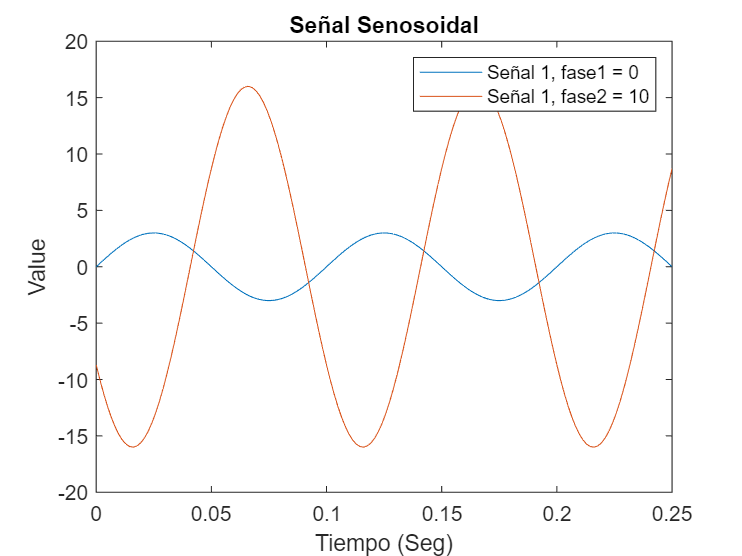

t = 0:1/fs:T;
figure
plot(t,y1) %Señal 1
hold on
plot(t,y2) %Señal 2
title("Señal Senosoidal")
xlabel("Tiempo (Seg)")
ylabel("Value")
legend("Señal 1, fase1 = 0", "Señal 1, fase2 = 10")